# DVB-S2 Transmitter Using Software-Defined Radio

This example shows how to generate Digital Video Broadcasting Satellite Second Generation (DVB-S2) physical layer (PL) frames and transmit them over-the-air using PSK software-defined radio (SDR) device or store them in a file. You can decode the PL frames using the `DVB-S2` `Receiver` `Using` `Software`-`Defined` `Radio` example with an additional SDR hardware device.

## Introduction

For this example, use a `dvbs2WaveformGenerator` System object™ to generate a DVB-S2 baseband waveform configured to the specified parameters. Transmit the generated waveform over-the-air using the `SDRu` transmitter System object and SDR hardware.

This example supports these SDRs.

- ADALM-PLUTO (requires Communications Toolbox™ Support Package for Analog Devices® ADALM-PLUTO Radio)

- USRP™ B200/B210/N200/N210/USRP2 (requires Communications Toolbox Support Package for USRP™ Radio)

The SDR device in this setup transmits DVB-S2 in-phase and quadrature phase (IQ) samples at the specified frequency and a symbol rate of 1 Msps.

This diagram summarizes the transmission process.

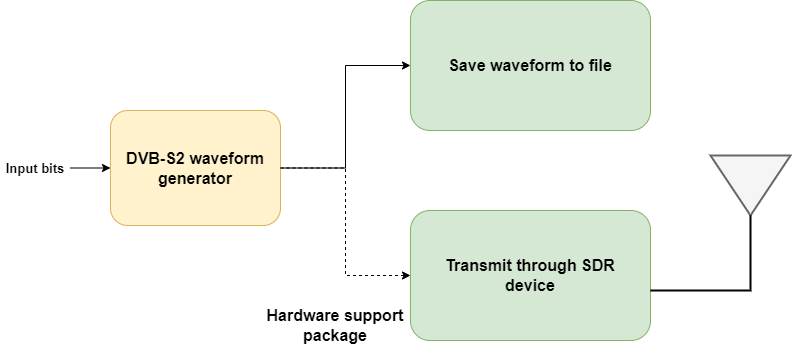

## Download DVB-S2 LDPC Parity Matrices Data Set

Load a MAT file containing DVB-S2 LDPC parity matrices. If the MAT file is not available on the MATLAB® path, use these commands to download and unzip the MAT file.

if ~exist('dvbs2xLDPCParityMatrices.mat','file')
    if ~exist('s2xLDPCParityMatrices.zip','file')
        url = 'https://ssd.mathworks.com/supportfiles/spc/satcom/DVB/s2xLDPCParityMatrices.zip';
        websave('s2xLDPCParityMatrices.zip',url);
        unzip('s2xLDPCParityMatrices.zip');
    end
    addpath('s2xLDPCParityMatrices');
end

## **Example Setup**

You can write the DVB-S2 waveform to a file or transmit it using an SDR platform. To transmit the waveform using an SDR platform, set `useSDR` to `true`.

useSDR = true;

If you set `useSDR` to `true`, configure the variables required for SDR transmission.

if useSDR
    txsim.DeviceName = "Pluto";
    txsim.RadioCenterFrequency = 915e6;
    txsim.RadioGain = 0;
end

## DVB-S2 Configuration Setup

Initialize a `dvbs2WaveformGenerator` System object and set its properties.

wg = dvbs2WaveformGenerator;
wg.FECFrame = "short";
wg.MODCOD = 18;                               % 32APSK 3/4
wg.DFL = getDFL(wg.MODCOD,wg.FECFrame);       % Default DFL is Kbch-80
wg.SamplesPerSymbol = 1

wg =   dvbs2WaveformGenerator with properties:

           StreamFormat: "TS"
        NumInputStreams: 1
               FECFrame: "short"
                 MODCOD: 18
                    DFL: 10552
          ScalingMethod: "outer radius as 1"
              HasPilots: 0
          RolloffFactor: 0.3500
    FilterSpanInSymbols: 10
       SamplesPerSymbol: 1

  Show all properties


wg.StreamFormat = "GS"

wg =   dvbs2WaveformGenerator with properties:

           StreamFormat: "GS"
        NumInputStreams: 1
                    UPL: 0
               FECFrame: "short"
                 MODCOD: 18
                    DFL: 10552
          ScalingMethod: "outer radius as 1"
              HasPilots: 0
          RolloffFactor: 0.3500
    FilterSpanInSymbols: 10
       SamplesPerSymbol: 1


wg.UPL = 8568;

## Generate Input Data

Generate input data in the form of packets, with the first byte being the sync byte. Concatenate multiple packets to create a frame of `DFL` length. Generate 50 frames.

numFrames = 48;                                           % Number of PL frames to be processed
rng("default")
if strcmpi(wg.StreamFormat,"TS")
    syncBits = [0 1 0 0 0 1 1 1]';                        % Sync byte for TS packet is 47 Hex
    pktLen = 1496;                                        % UP length without sync bits is 1496
else
    if wg.UPL
        syncBits = randi([0 1],8,1);
        pktLen = wg.UPL - 8;                              % UP length without sync byte
    end
end
% For GS continuous streams
if strcmpi(wg.StreamFormat,"GS") && wg.UPL == 0
    numBits = wg.DFL*numFrames;
    data = randi([0 1],numBits,1);
else % For TS and GS packetized streams
    numPkts = wg.MinNumPackets*numFrames;
    %txRawPkts = randi([0 1],pktLen,numPkts);
    %txRawPkts = ones(pktLen,numPkts);
    load("pic.mat");
    pic_bitstream = [bitstream; zeros(pktLen*numPkts-length(bitstream), 1)]
    txRawPkts = reshape(pic_bitstream, pktLen, numPkts);

    txPkts = [repmat(syncBits,1,numPkts); txRawPkts];
    data = txPkts(:);
end

pic_bitstream =      0
     0
     0
     0
     0
     0
     0
     1
     0
     1


## Generate DVB-S2 Waveform

Generate DVB-S2 baseband waveform in pilot-aided mode.

wg.HasPilots = true;
txOut = [wg(data); flushFilter(wg)];

## **Configure SDR for Transmission**

Discover radio(s) connected to your computer. This example uses the first SDR radio found using the `txsim.DeviceName` and `findsdru` function. Check if the radio is available and record the radio type. Initialize `sdrtx` or `comm.SDRuTransmitter` System object. Set the platform, center frequency, sample rate, gain, and other relevant properties. Transmit the DVB-S2 waveform over-the-air using SDR device.

Rsym = 1e6;
Fsamp = Rsym*wg.SamplesPerSymbol;                                                % Sampling rate in samples per second
if useSDR
    if matches(txsim.DeviceName,"Pluto")
        frameSize = getFrameSize(wg.FECFrame,wg.MODCOD)*wg.SamplesPerSymbol;
        radioTx = sdrtx("Pluto");
        radioTx.RadioID               = "usb:0";
        radioTx.CenterFrequency       = txsim.RadioCenterFrequency;
        radioTx.BasebandSampleRate    = Fsamp;
        radioTx.SamplesPerFrame       = frameSize;
        radioTx.Gain                  = txsim.RadioGain;
    else
        connectedRadios = findsdru;
        rIdx = find(strcmp(txsim.DeviceName,{connectedRadios.Platform}));
        if strcmp(connectedRadios(rIdx).Status,"Success")
            usrpTx.Platform = connectedRadios(rIdx).Platform;
            switch usrpTx.Platform
                case {'B200','B210'}
                    usrpTx.SerialNum = connectedRadios(rIdx).SerialNum;
                    usrpTx.MasterClockRate = 20e6;
                case 'N200/N210/USRP2'
                    usrpTx.Address = connectedRadios(rIdx).IPAddress;
                    usrpTx.MasterClockRate = 100e6;
                otherwise
                    error("%s\n","Unsupported USRP device")
            end
        end
        usrpTx.Gain = txsim.RadioGain;                                            % In dB
        switch usrpTx.Platform
            case {'B200','B210'}
                radioTx = comm.SDRuTransmitter( ...
                    Platform             = usrpTx.Platform, ...
                    SerialNum            = usrpTx.SerialNum, ...
                    CenterFrequency      = txsim.RadioCenterFrequency, ...
                    MasterClockRate      = usrpTx.MasterClockRate, ...
                    InterpolationFactor  = usrpTx.MasterClockRate/Fsamp, ...
                    Gain                 = usrpTx.Gain);
            case 'N200/N210/USRP2'
                radioTx = comm.SDRuTransmitter(...
                    Platform            = usrpTx.Platform, ...
                    IPAddress           = usrpTx.Address, ...
                    CenterFrequency     = txsim.RadioCenterFrequency, ...
                    Gain                = usrpTx.Gain, ...
                    InterpolationFactor = usrpTx.MasterClockRate/Fsamp);
        end
    end
    numRepeatTxFrames = 10000;                                                     % Waveform is repeatedly transmitted in a loop
    disp(radioTx)
    fprintf("Starting transmission at Fs = %g MHz\n",Fsamp/1e6)
    for frame = 1:numRepeatTxFrames
        underrun = radioTx(txOut);
        if (underrun) 
            warning("Dropped samples.")
        end
    end
    fprintf("Transmission finished\n")
    release(radioTx)

  comm.SDRTxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 915000000
                      Gain: 0
            ChannelMapping: 1
        BasebandSampleRate: 1000000
    ShowAdvancedProperties: false

  Show all properties



Starting transmission at Fs = 1 MHz


## Establishing connection to hardware. This process can take several seconds.


## **Save Waveform to File**

Save the waveform in a MAT file.

else
    fprintf("Writing DVB-S2 IQ samples into a file\n")
    filename = "dvbs2ModCod" + string(wg.MODCOD) + "Waveform.mat";
    save(filename,'txOut')
end
release(wg)

## **Further Exploration**

The companion example `DVB-S2 Receiver Using Software-Defined Radio` example can be used to decode the waveform transmitted by this example.

## **SDR Troubleshooting**

- ADALM-PLUTO Radio [Common Problems and Fixes](docid:plutoradio_ug#bvn89q2-68) (Communications Toolbox Support Package for Analog Devices ADALM-Pluto Radio)

- USRP Radio [Common Problems and Fixes](docid:usrpradio_ug#bud4heb-1)

## References

-  ETSI Standard EN 302 307-1 V1.4.1(2014-11). *Digital Video Broadcasting (DVB); Second Generation Framing Structure, Channel Coding and Modulation Systems for Broadcasting, Interactive Services, News Gathering and other Broadband Satellite Applications (DVB-S2)*.

## Local Functions

function dfl = getDFL(modCod,fecFrame)
% Get data field length
if strcmp(fecFrame,"normal")
    nDefVal = [16008 21408 25728 32208 38688 43040 48408 51648 53840 57472 ...
        58192 38688 43040 48408 53840 57472 58192 43040 48408 51648 53840 ...
        57472 58192 48408 51648 53840 57472 58192] - 80;
else
    nDefVal = [3072 5232 6312 7032 9552 10632 11712 12432 13152 14232 0 ...
        9552 10632 11712 13152 14232 0 10632 11712 12432 13152 14232 0 11712 ...
        12432 13152 14232 0] - 80;
end
dfl = nDefVal(modCod);
end
function frameSize = getFrameSize(fecFrame,modCod)
% Get PL frame size
[modOrder,~,cwLen] = satcom.internal.dvbs.getS2PHYParams(modCod,fecFrame);
dataLen = cwLen/log2(modOrder);
% Pilot sequence and indices generation
slotLen = 90;
pilotBlkFreq = 16;                                                              % In slots
numPilotBlks = floor(dataLen/(slotLen*pilotBlkFreq));
if floor(dataLen/(slotLen*16)) == dataLen/(slotLen*pilotBlkFreq)
    numPilotBlks = numPilotBlks - 1;
end
pilotLen = numPilotBlks*36;                                                     % One pilot block contains 36 pilot symbols
frameSize = dataLen + pilotLen + slotLen;
end

*Copyright 2023 The MathWorks, Inc.*